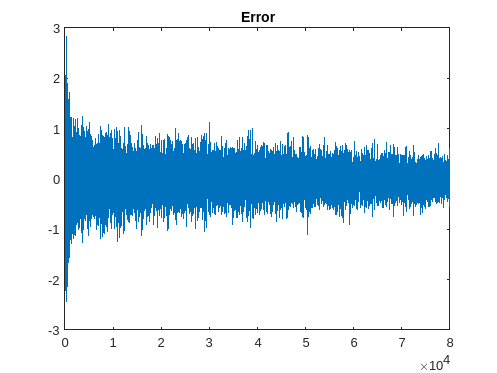

Equalizer = load("EqualizerData.mat");

%sets the sampling frequency to 48kilosamples per second
Fs = 48000;

%Listen to the music file
music = audioplayer(Equalizer.x2,Fs);
%playblocking(music);


%sets the length of our filter
filterLength = 80;

%creates the h_init filter
h_initial = zeros([filterLength 1]);

%sets the mu for propogation
mu = 0.001;


%creates M_hat_g which is our estimate of the time delay
M_hat_g = 56;

%creates the time delay of t, which is the average of M_hat_g and
%filterLength
time_delay = (filterLength + M_hat_g)/2;

%creates the time delayed version of t
zeroPad = zeros([time_delay 1]);
timeDelayedT = cat(1,zeroPad,Equalizer.t);


%calls the lms function to create the new filter and output function
[v, e, h] = lms(Equalizer.z, timeDelayedT, mu, h_initial);


%plots the error as the system propogates
plot(e);
title("Error");

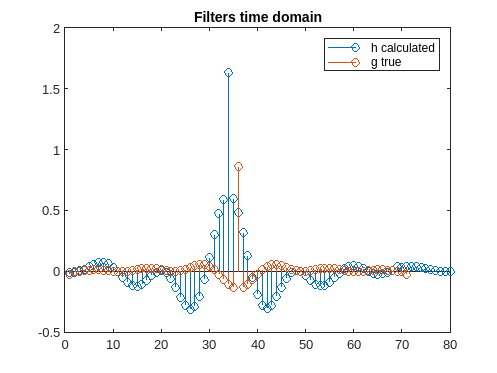


%plots the h filter
stem(h);
hold on;
title("Filters time domain");
%also plots the g filter on the same grid
stem(Equalizer.g_true);
legend("h calculated", "g true");
hold off;

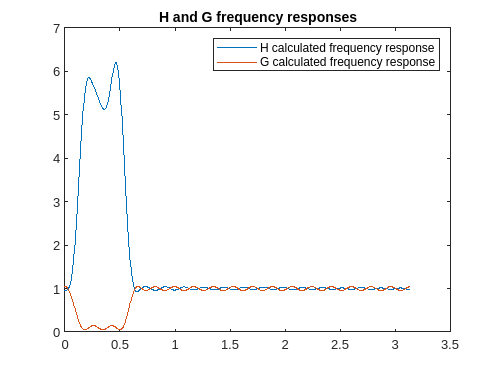


%plots the frequency responses of the two filters
[h_frequency_response, w_0] = freqz(h,1,1000);
[g_frequency_response, w_1] = freqz(Equalizer.g_true,1,1000);

plot(w_0,abs(h_frequency_response));
title("H and G frequency responses");
hold on;
plot(w_0, abs(g_frequency_response));
legend("H calculated frequency response", "G calculated frequency response");
hold off;

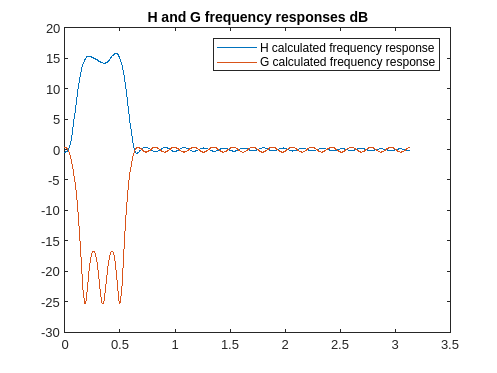



plot(w_0,20*log10(abs(h_frequency_response)));
title("H and G frequency responses dB");
hold on;
plot(w_0, 20*log10(abs(g_frequency_response)));
legend("H calculated frequency response", "G calculated frequency response");
hold off;




%filters the z2 signal
filteredz2 = filter(h, 1, Equalizer.z2);
%plays the filtered signal
filteredSignalAudio = audioplayer(filteredz2,Fs);
playblocking(filteredSignalAudio);


